# DH Parameters

Denavit-Hartenberg (DH) Parameters are a widely-used method to specify the structure of a robot manipulator. 

In the previous script, we looked at how transformation matrices can help in transforming from any cartesian coordinate system to any other cartesian coordinate system as long as we can specify the 1) Rotation and 2) Translation Matrices.

DH parameters offer a convenient, widely-used notation to specify these transformations for industrial robots.

First, let us see how Transformation Matrices can transform between two different coordinate systems:

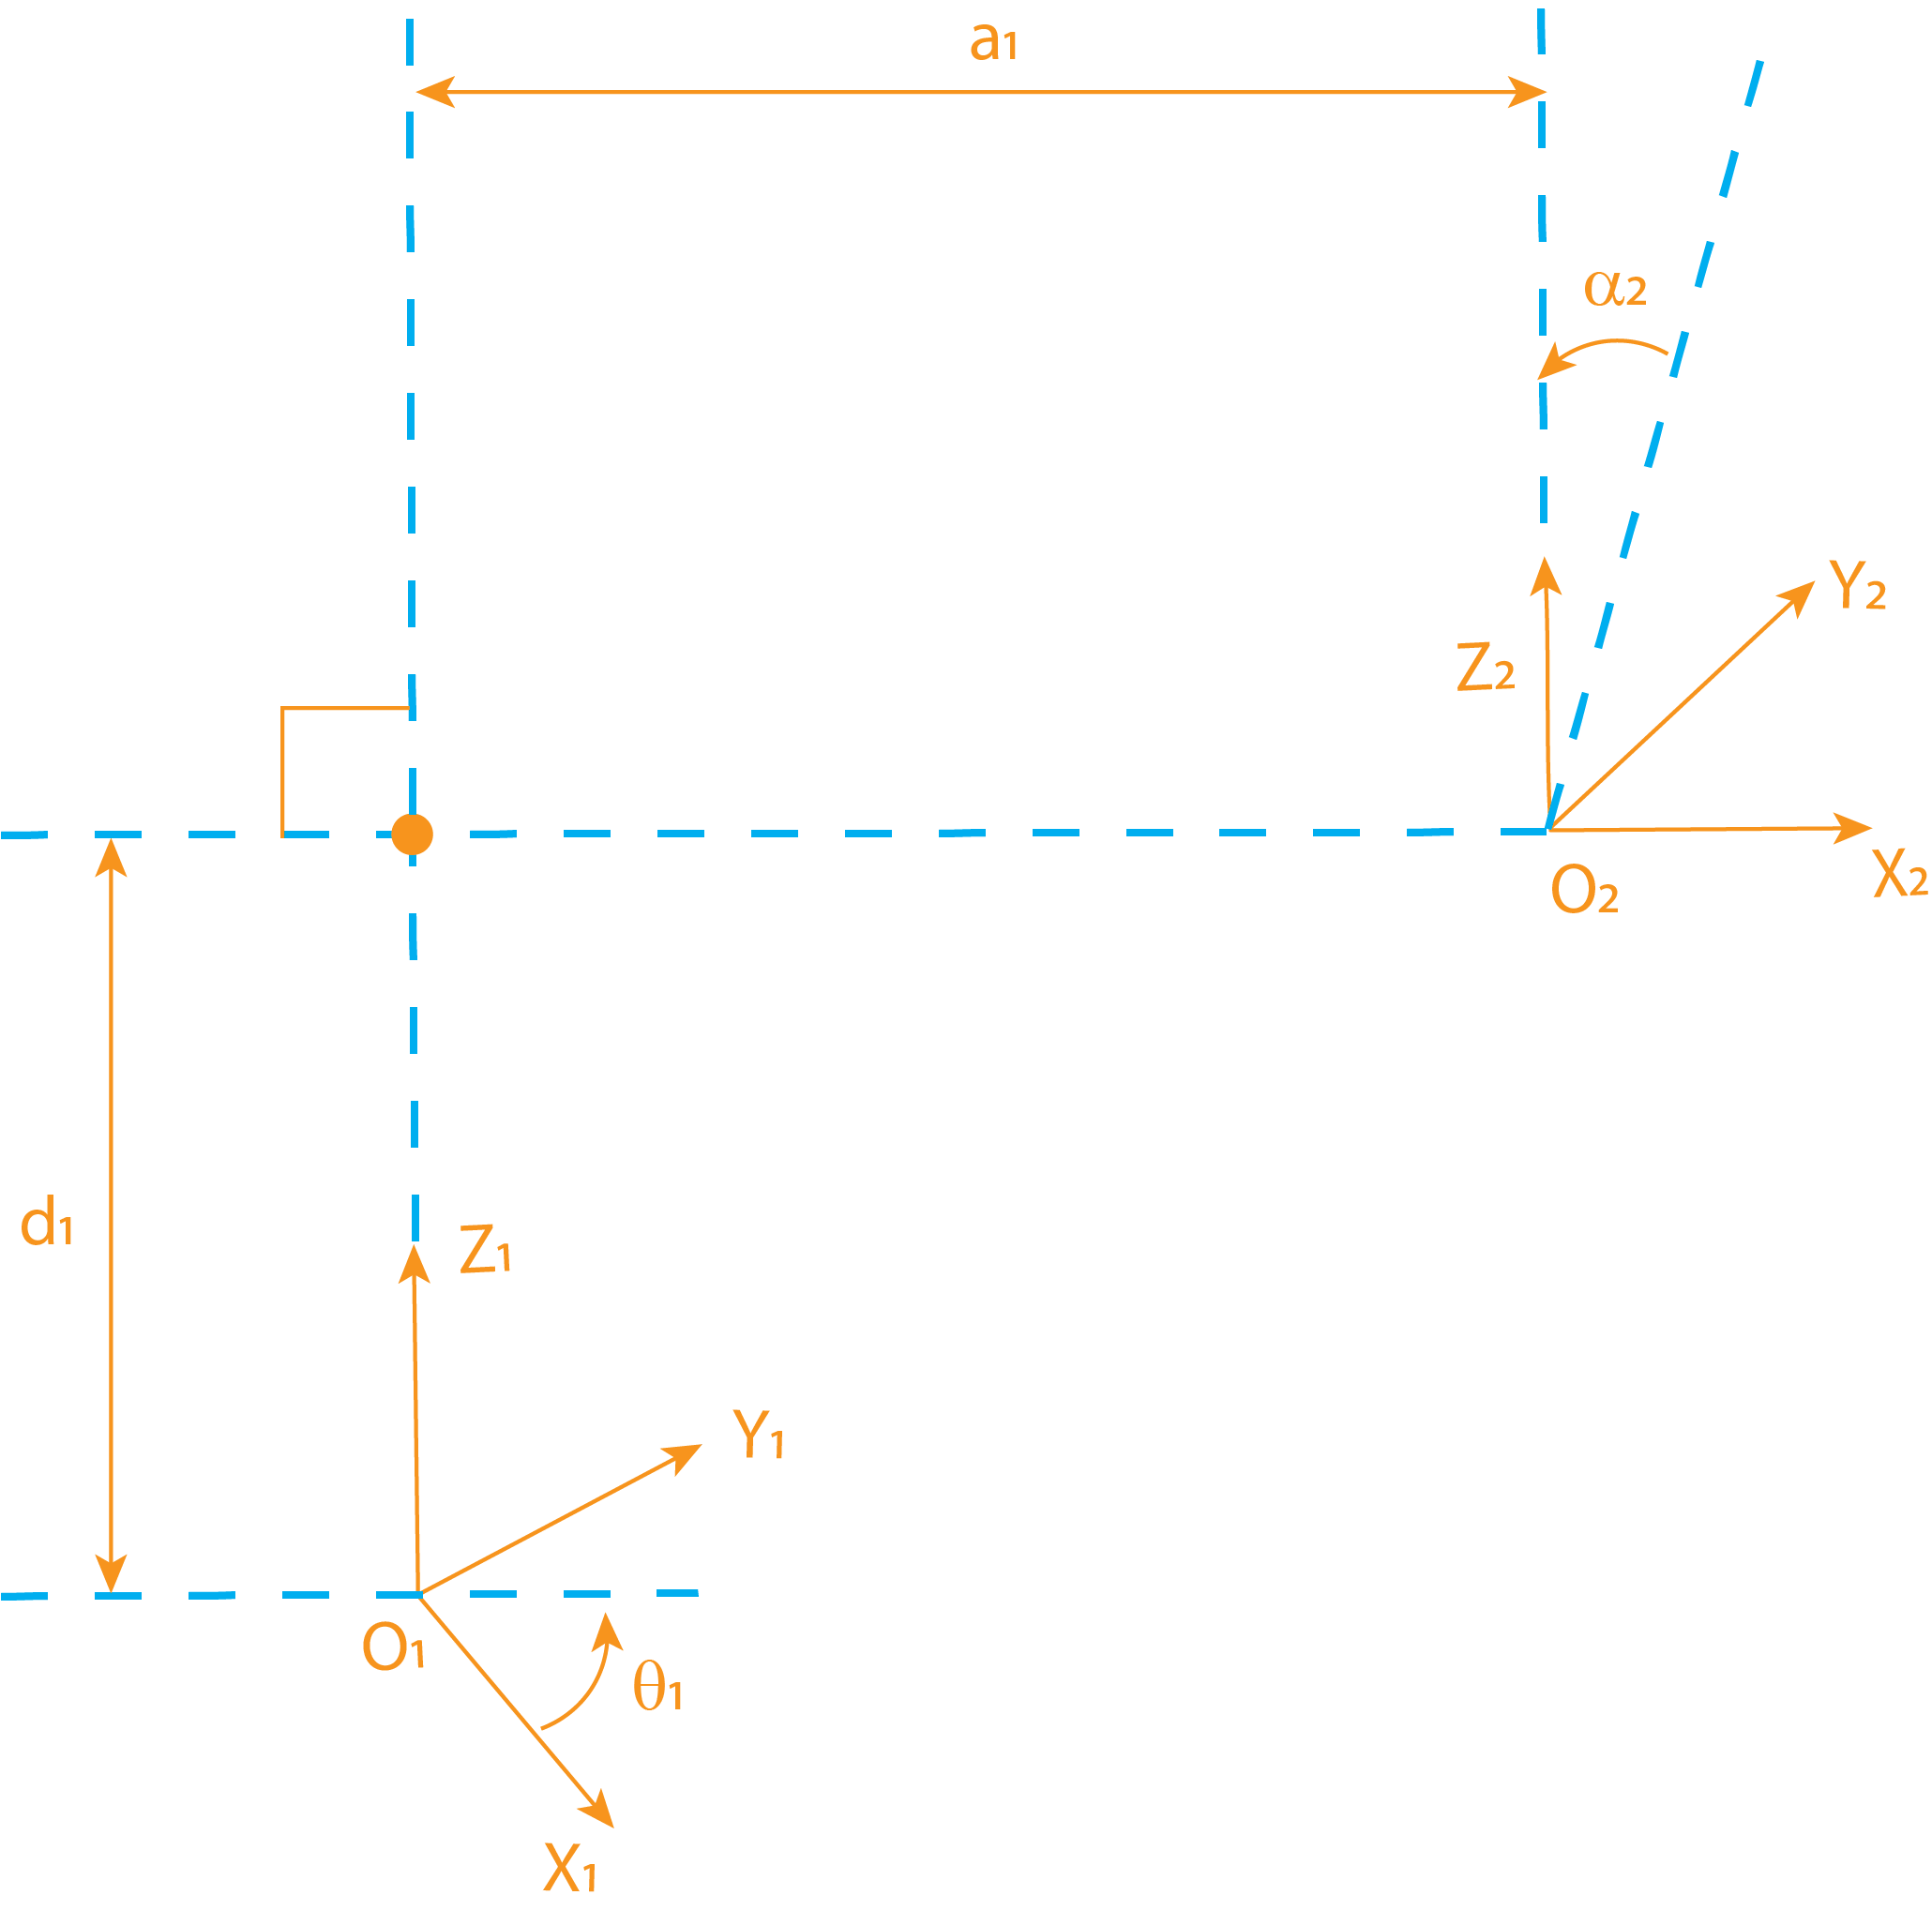

The assumption in DH parameters is that any coordinate system for an industrial manipulator can be represented using just 4 operations in the following sequence:

- Rotation of angle $\theta$about the z-axis

- Translation of distance *d* along the z-axis

- Translation of distance *a *along the x-axis

- Rotation of angle $\alpha$ about the x-axis

Therefore,


$$T={\textrm{Rot}}_{z,\theta } \cdot {\textrm{Trans}}_{z,d} \cdot \;{\textrm{Trans}}_{x,a\;} \cdot \;{\textrm{Rot}}_{x,\alpha }$$



$$T=\left\lbrack \begin{array}{cccc}
C\theta  & -S\theta \cdot C\alpha  & S\theta  & a\cdot C\theta \\
S\theta  & C\theta \cdot C\alpha  & -C\theta \cdot S\alpha  & a\cdot S\theta \\
0 & S\alpha  & C\alpha  & d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


where, $C\theta =\cos \left(\theta \right)\;\textrm{and}\;S\theta =\sin \left(\theta \right)$

For the 4 DH parameters (α, a, d, θ), in all occasions 3 of them will be fixed. The remaining one will move according to the joint type: 

- d if the joint is prismatic

- θ if the joint is revolute

So for an example robot, let us see how the Transformation Matrices can be created using DH Parameters.

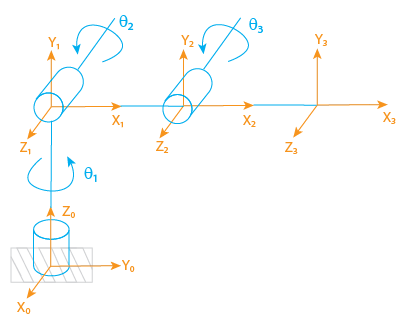

Let us assume that the 'global' coordinate frame coincides with the base coordinate system.

%definition of the link lengths and angles
a1 = 0  ; d1 = 2  ; alpha1 = pi/2 ; th1 = 0;
a2 = 1  ; d2 = 0  ; alpha2 = 0    ; th2 = pi/4;
a3 = 1  ; d3 = 0  ; alpha3 = 0    ; th3 = -pi/4;

T01 = dh_param(a1,d1,alpha1,th1)

T01 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    2.0000
         0         0         0    1.0000


T12 = dh_param(a2,d2,alpha2,th2)

T12 =     0.5403   -0.8415         0    0.4244
    0.8415    0.5403         0    0.6609
         0         0    1.0000         0
         0         0         0    1.0000


T23 = dh_param(a3,d3,alpha3,th3)

T23 =     0.5403   -0.8415         0   -0.4244
    0.8415    0.5403         0   -0.6609
         0         0    1.0000         0
         0         0         0    1.0000



T03 = T01*T12*T23

T03 =    -0.4161   -0.9093         0    0.7512
    0.0000   -0.0000   -1.0000   -0.0000
    0.9093   -0.4161    0.0000    1.9467
         0         0         0    1.0000


Therefore, if any point 'p' is at some coordinate in the base-frame, we can get it's position with respect to the end-effector as:

p = [4 0 2 0] %(x,y,z,0)

p =      4     0     2     0



p3 = p*T03

p3 =     0.1540   -4.4695    0.0000    6.8982


To verify, we can do the calculation in reverse.

T30 = inv(T03)

T30 =    -0.4161    0.0000    0.9093   -1.4575
   -0.9093   -0.0000   -0.4161    1.4932
         0   -1.0000    0.0000   -0.0000
         0         0         0    1.0000



p0 = p3*T30

p0 =     4.0000         0    2.0000   -0.0000


Thus we can transform any coordinate from the base-frame into the reference frame of any joint of the robot or the end-effector, and back, using DH Parameters.

The next step typically is to put all of this into a single structure and function and then change the values of the robot joints to see how the position changes.

function T = dh_param(theta,d,alpha,a)
% This function generates a transformation matrix T
% depending on input dh parameters 
% theta, d, alpha and a

% calculating sin-cos for theta and alpha
St = sin(theta);
Ct = cos(theta);

Sa = sin(alpha);
Ca = cos(alpha);

% calculating matrix
T = [Ct -St*Ca St*Sa  a*Ct;...
     St Ct*Ca  -Ct*Sa a*St;...
     0  Sa     Ca     d   ;...
     0  0      0      1  ];

end